# Simple Harmonic Motion

## Introduction

In mechanics and physics, simple harmonic motion is a special type of periodic motion where the restoring force on the moving object is directly proportional to the magnitude of the object's displacement and acts towards the object's equilibrium position.

In this activity we will learn how to use MATLAB to model and plot approximate solutions for the simple harmonic motion of the spring.

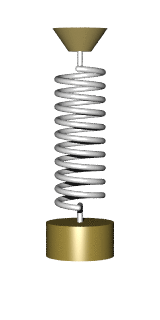

## **Before starting**

Use the **MATLAB** **Live Editor** to **edit** and **run** this **Live Script** in your browser or your desktop.

- Read each section carefully. 

- Run the code within a section before starting to read the next. 

- To run the code from each section, position the *cursor* on the code with the mouse and then click on the **Run Section** button (from the toolstrip) or click on the blue stripe on left side of that section as shown below:

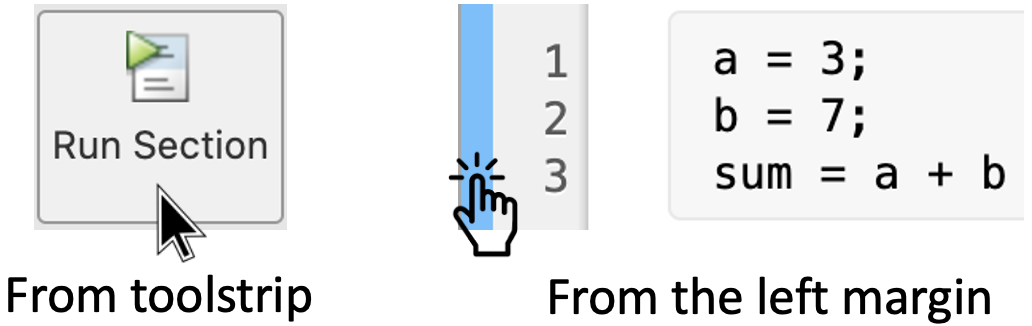

**Remark:** Run the code of each section from top to bottom, otherwise you may get an error.

- *The end of a section is indicated with a thin line, like the next one* -

## 1. The motion of a spring-mass system

### 1.2 The undamped spring			

A spring of (natural) length $L$ is stretched a distance $s$ by a weight with mass $m$. In equilibrium we take the position of the weight (viewed as a point-particle) to be $x =0$ with the positive $x$-axis pointing down. 

If we pull down the weight and then release it, it will start to oscillate. 

If we assume the weight-spring-system moves free of any resistance (no air-resistance and no internal friction in the spring) we say the spring is undamped.

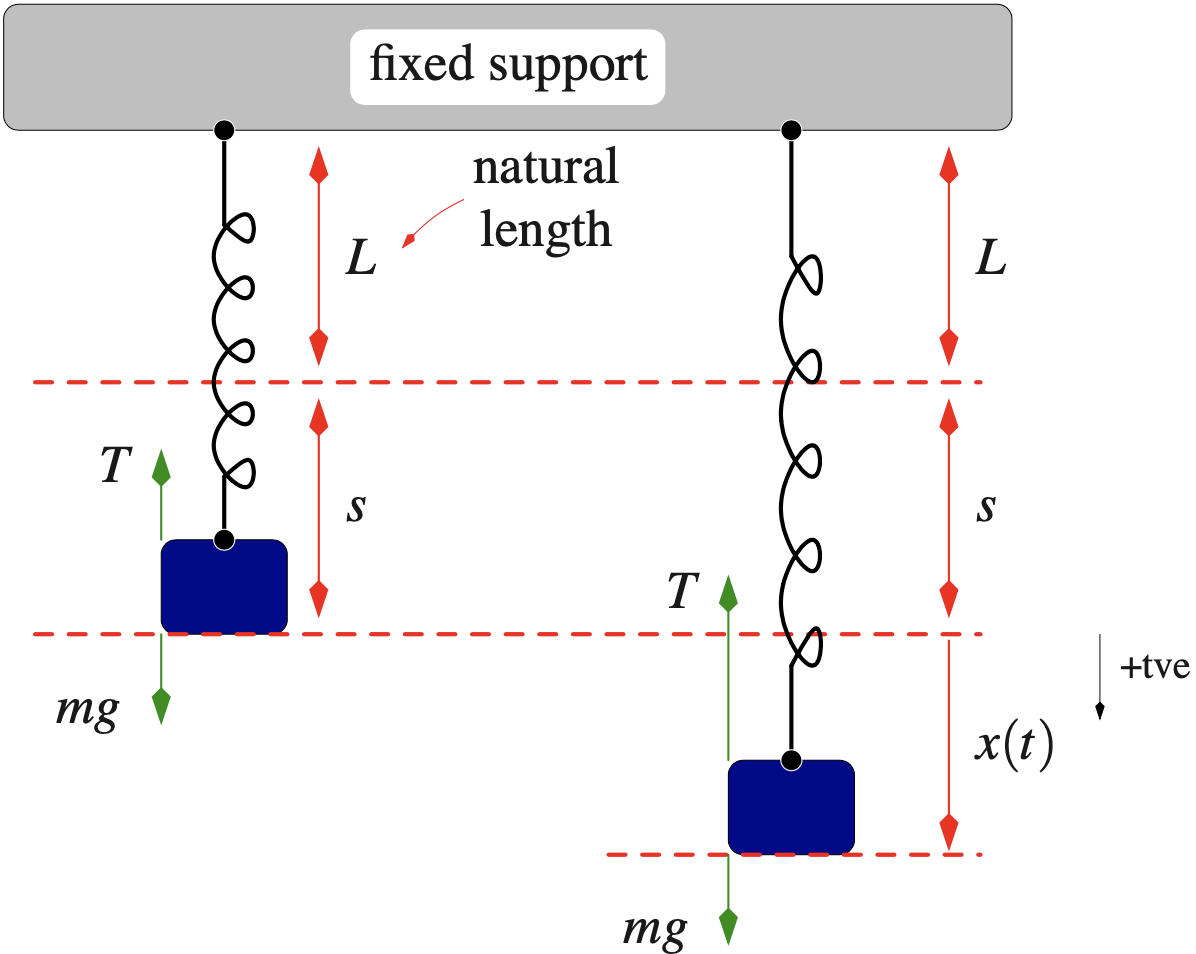

We know that the equation of motion for the undamped spring is given by

$x^{\prime\prime}+\frac{k}{m}x=0$,

where $k$ is the known as the spring constant, and $m$ represents the mass. Observe that this is a homogeneous second-order linear ODE with constant coefficients, which can be expressed as the couple system of equations


$$\begin{array}{ll}
x'=y\\
y'=-\frac{k}{m}x
\end{array}$$


Using this system, we can easily solve Initial Value Problems (IVP) in MATLAB. For example, consider the following

**Problem 1:** A mass of 9kg is attached to a spring with spring constant 4N/m. The spring is pulled down 1m and given an initial upward kick of -0.5 m/s. Compute and plot a numerical solution.

From the information provided we have that

- 
$$k=4$$


- 
$$m=9$$


- 
$$x(0)=1$$


- 
$$x'(0)=-0.5$$


### 1.3 Implementation in MATLAB

The following MATLAB code computes and plots an approximated solution of the IVP from Problem 1.

t0 = 0;     % Initial time
tf = 50;    % Final time, here we have chosen 50
x0 = 1;     % Initial condition x(0)=1
y0 = -0.5;  % Initial condition x'(0)=-0.5

k = 3;      % Spring constant
m = 5;      % Mass

% Define anonymous function for the system
secODEUndampedSprg = @(t,Y) [Y(2); -k/m * Y(1)];

[T,Y] = ode45(secODEUndampedSprg, [t0, tf], [x0; y0]);

% Plot solutions
plot(T, Y(:,1), 'r-', 'LineWidth', 1.5);

% Add extra feature to the plot
title('Motion for the undamped spring')
xlabel('t')
ylabel('x(t)')
grid on
axis([t0 tf -2 2])

## 2. Hands on Practice

### Activity: The damped spring

For a more realistic model for the spring, we need to consider the effect of damping. This is caused by air-resistance and mechanical friction of the spring. We know that this can be represented by the equation


$$x''+\frac{\beta}{m}x'+\frac{k}{m}x=0$$


where $\beta$ is the damping constant, $k$ the spring coefficient and $m$ the mass.

First, in your notebook, re-write this equation as a system of ODE. Then in MATLAB:

- Compute the constant $D=4\left(\frac{\beta^2}{4m^2}-\frac{k}{m}\right)$

- Compute an approximated solution for each IVP defined below.

- Plot the solution.

- Analyse the relationship between the constant $D$ and the solution of the IVP.

### Part 1) Underdamped spring

Consider $k=1$, $m=1$, $\beta=0.2$ and initial conditions $x(0)=1$, $x'(0)=0$. Plot the solution on the interval $[0,60]$.

Write your code here:

### Part 2) Critically damped spring

Consider $k=1$, $m=1$, $\beta=2$ and initial conditions $x(0)=1$, $x'(0)=2$. Plot the solution on the interval $[0,10]$.

Write your code here:

### Part 3) Overdamped spring

Consider $k=10$, $m=1$, $\beta=10$ and initial conditions $x(0)=0$, $x'(0)=1$. Plot the solution on the interval $[0,6]$.

Write your code here: